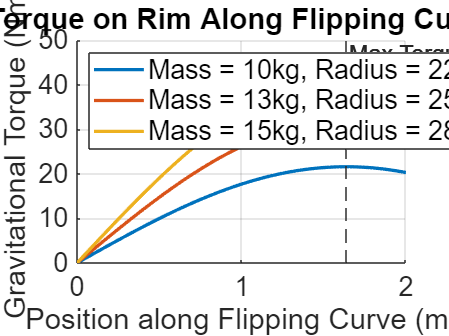

% Rim Flip Simulation - Confirming Torque for Various Rim Types

% Parameters
rim_radii = [0.22, 0.25, 0.28]; % meters
rim_masses = [10, 13, 15];      % kg
g = 9.81;                       % m/s^2
curve_length = 2;              % meters
conveyor_speed = 0.5;          % m/s
tilt_target_deg = 110;
tilt_target_rad = deg2rad(tilt_target_deg);

% Curve profile - assume constant angular rise
theta_vals = linspace(0, tilt_target_rad, 100);  % tilt angle from 0 to 110°
curve_positions = linspace(0, curve_length, 100); % corresponding positions along curve

% Plotting
figure;
hold on;

for i = 1:length(rim_masses)
    m = rim_masses(i);
    r = rim_radii(i);
    torque = m * g * r * sin(theta_vals);  % Gravitational torque

    [max_torque, idx] = max(torque);
    max_pos = curve_positions(idx);
    xline(max_pos, '--', sprintf('Max Torque (%.2f m)', max_pos), ...
        'LabelOrientation','horizontal', 'FontSize', 14, 'HandleVisibility', 'off');
    
    plot(curve_positions, torque, 'LineWidth', 2, 'DisplayName', ...
        sprintf('Mass = %dkg, Radius = %.0fmm', m, r*1000));
end

xlabel('Position along Flipping Curve (m)', 'FontSize', 20);
ylabel('Gravitational Torque (Nm)', 'FontSize', 20);
title('Torque on Rim Along Flipping Curve', 'FontSize', 22);

legend('FontSize', 16, 'Location', 'northwest');
grid on;

% Make tick labels larger
ax = gca;
ax.FontSize = 16;